# 3-D Point Cloud Registration and Stitching

This live script explains how to conduct ICP steps using matlab. It is heavily based on the Mathworks example:

http://www.mathworks.com/examples/matlab-computer-vision/mw/vision_product-StitchPointCloudsExample-3-d-point-cloud-registration-and-stitching?s_tid=srchtitle

This live script is part of the software package accompanying the "Autonomous Mobile Robot Design" course.

Author:

Kostas Alexis (kalexis@unr.ed)

## Overview

This example performs an algorithm called Iterative Closest Point (ICP) to combine poing clouds collected using an RGBD sensor (Kinect) and reconstruct the environment in 3D.

## Summary of ICP operations

In the ICP algorithm, one point cloud, the reference, or target, is kept fixed, while the other one, the source, is transformed to best match the reference. The algorithm iteratively revises the transformation (combination of translation and rotation) needed to minimize the distance from the source to the reference point cloud.

**Inputs: **reference and source point clouds, initial estimation of the transformation to align the source to the reference (optional), criteria for stopping the iterations.

Output: refined **transformation**.

**Essentially, the algorithm steps are:**

**1. **For each point in the source point cloud, find the closest point in the reference point cloud.

**2.** Estimate the combination of rotation and translation using a mean squared error cost function that will best align each source point to its match found in the previous step.

**3. **Transform the source points using the obtained transformation.

**4.** Iterate (re-associate the points, and so on).

There exist many ICP variants from which point-to-point and point-to-plane are the most popular. The latter usually performs better in structured environments.

dataFile = fullfile(toolboxdir('vision'), 'visiondata', 'livingRoom.mat');
load(dataFile);

ptCloudRef = livingRoomData{1};
ptCloudCurrent = livingRoomData{2};

The quality of registration depends on data noise and initial settings of the ICP algorithm. 

In order to attenuate the noise levels from the data and reduce the computational complexity, reduction through box-filtering can take place. For this test a box grid filter with a box edge size of 5cm is used. The box grid filter divides the point cloud space into cubes. Points within each cube are combined into a single output point by averaging their X,Y,Z coordinates.


gridSize = 0.05;
fixed = pcdownsample(ptCloudRef, 'gridAverage', gridSize);
moving = pcdownsample(ptCloudCurrent, 'gridAverage', gridSize);

It is noted that the box grid filtering leads to downsampling which obviously helps in computational reduction. In specific cases it can also benefit accuracy (when supporting noise reduction while allignment can still take place)

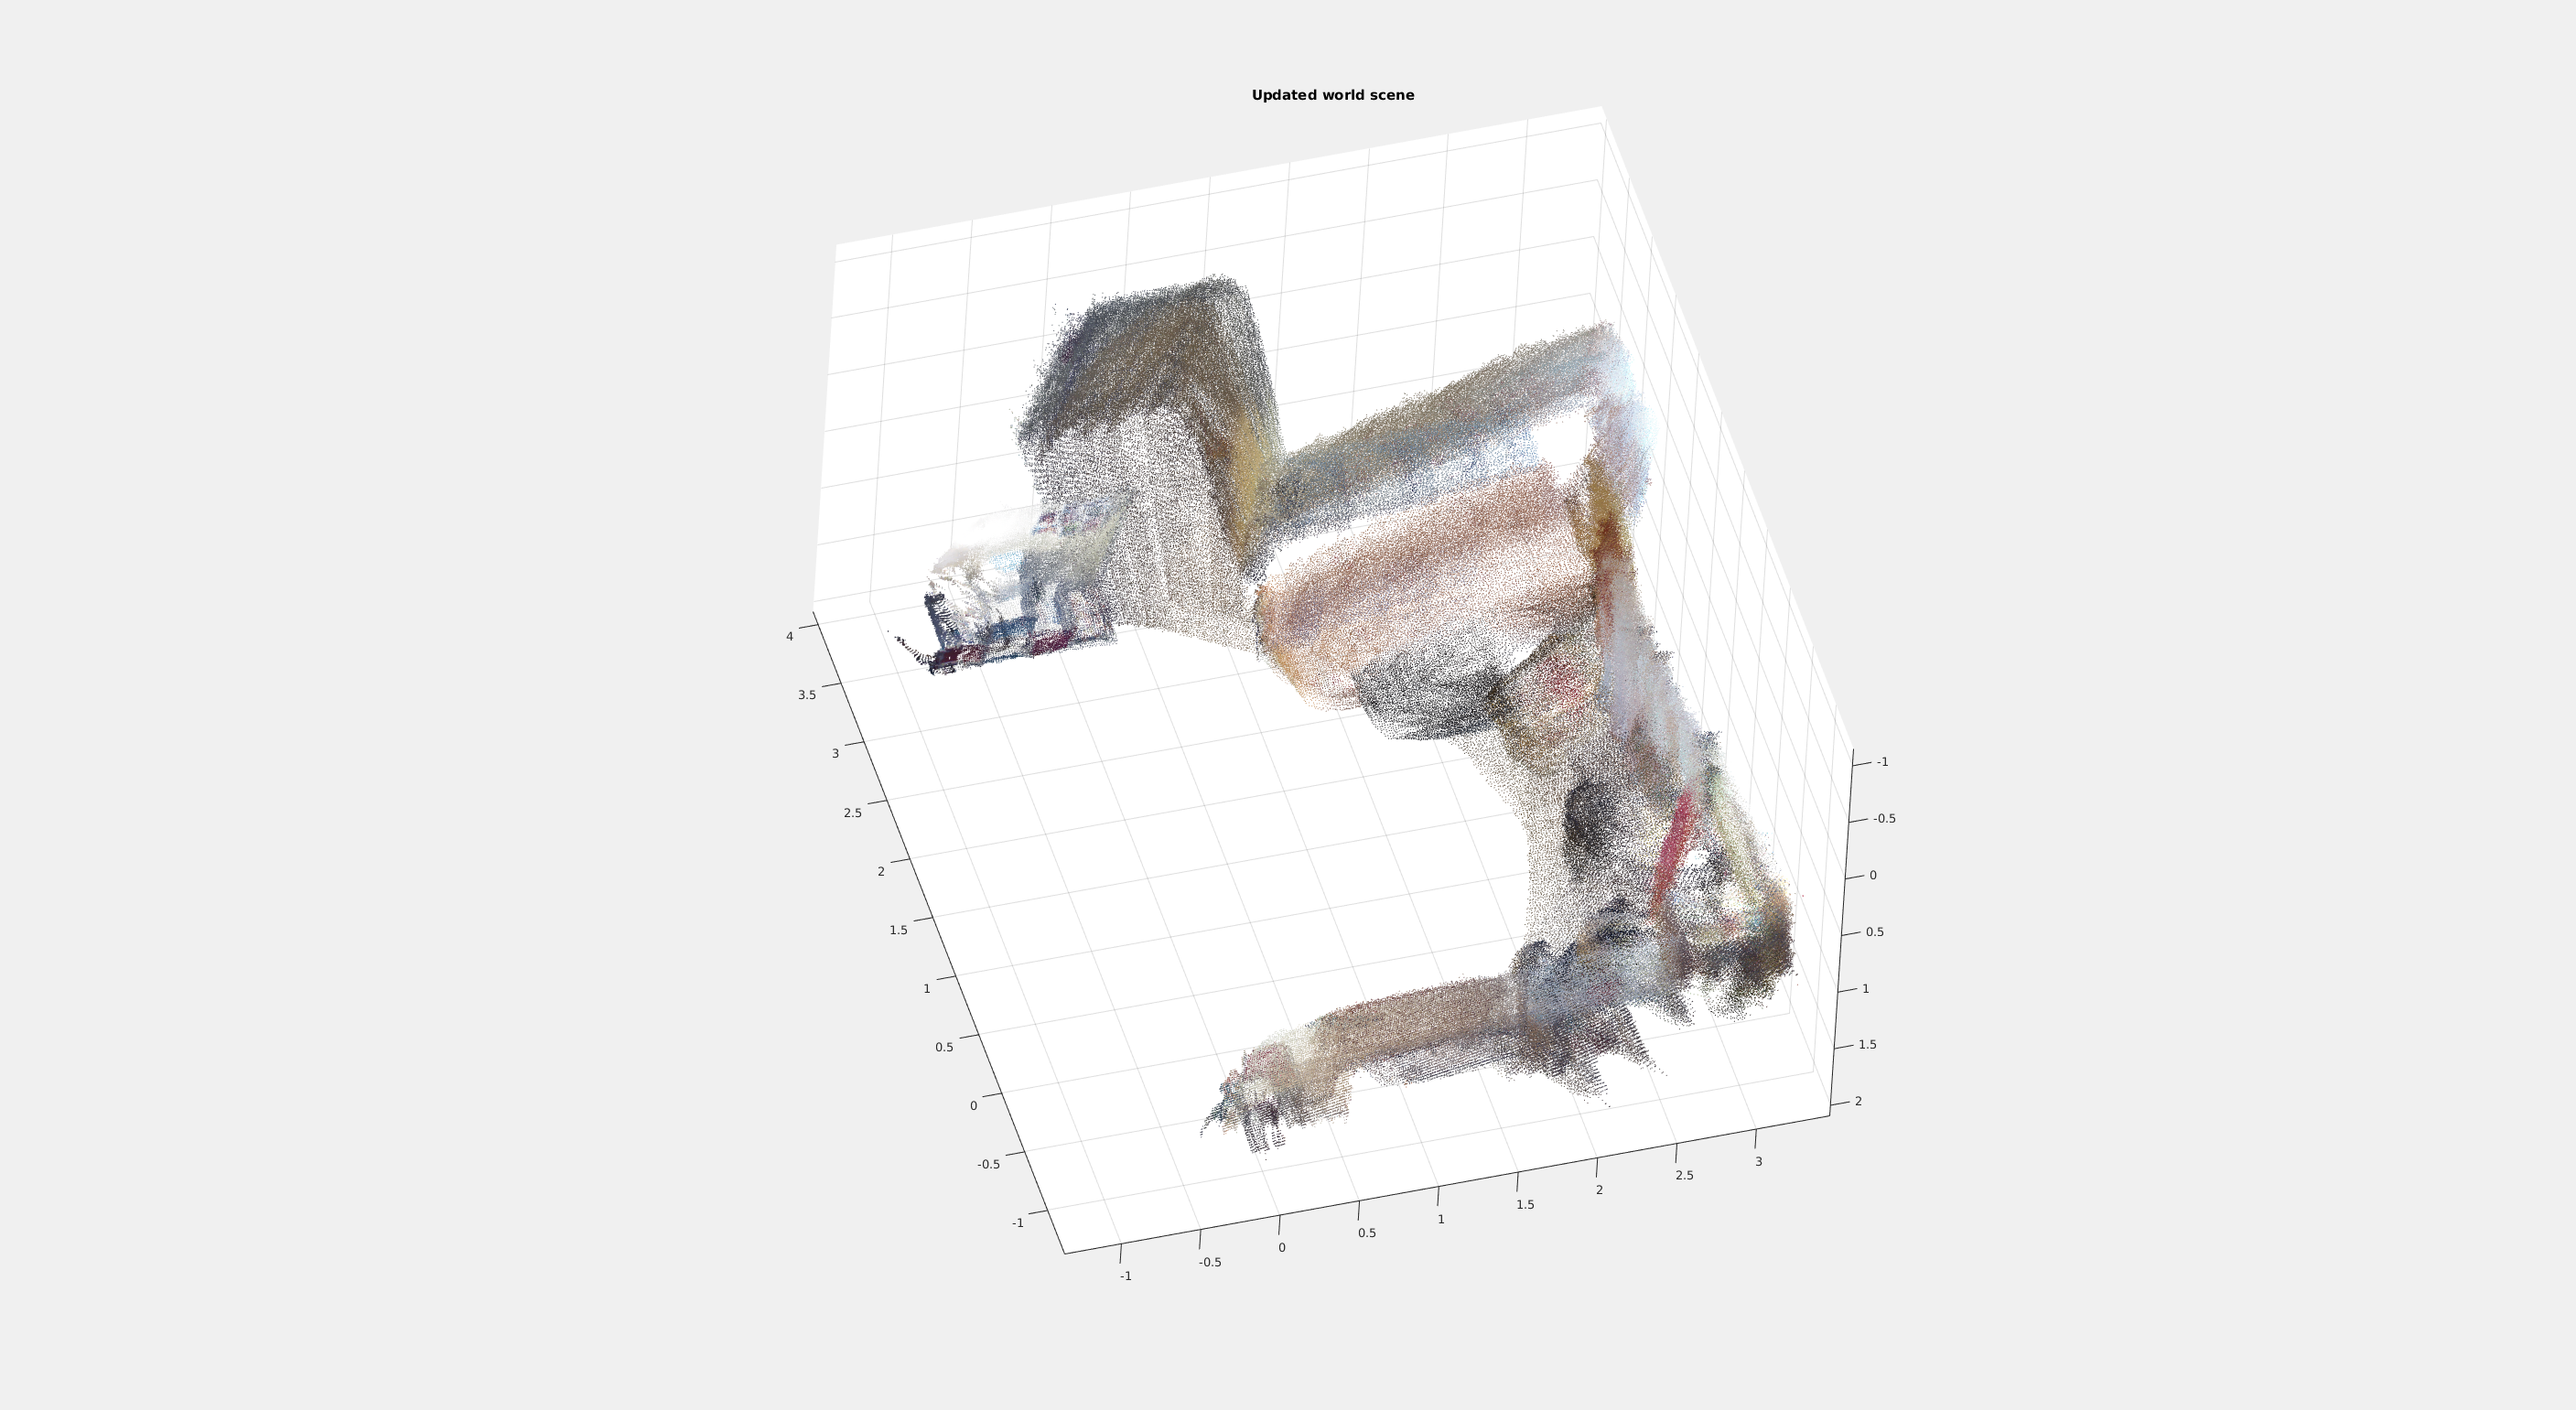

tform = pcregrigid(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
ptCloudAligned = pctransform(ptCloudCurrent,tform);

mergeSize = 0.015;
ptCloudScene = pcmerge(ptCloudRef, ptCloudAligned, mergeSize);

% Store the transformation object that accumulates the transformation.
accumTform = tform;

figure
hAxes = pcshow(ptCloudScene, 'VerticalAxis','Y', 'VerticalAxisDir', 'Down');
title('Updated world scene')
% Set the axes property for faster rendering
hAxes.CameraViewAngleMode = 'auto';
hScatter = hAxes.Children;

for i = 3:length(livingRoomData)
    ptCloudCurrent = livingRoomData{i};

    % Use previous moving point cloud as reference.
    fixed = moving;
    moving = pcdownsample(ptCloudCurrent, 'gridAverage', gridSize);

    % Apply ICP registration.
    tform = pcregrigid(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);

    % Transform the current point cloud to the reference coordinate system
    % defined by the first point cloud.
    accumTform = affine3d(tform.T * accumTform.T);
    ptCloudAligned = pctransform(ptCloudCurrent, accumTform);

    % Update the world scene.
    ptCloudScene = pcmerge(ptCloudScene, ptCloudAligned, mergeSize);

    % Visualize the world scene.
    hScatter.XData = ptCloudScene.Location(:,1);
    hScatter.YData = ptCloudScene.Location(:,2);
    hScatter.ZData = ptCloudScene.Location(:,3);
    hScatter.CData = ptCloudScene.Color;
    drawnow('limitrate')
end

Plotting the results. Some of this code is specific to viewing aspects and how the sensor is carried. 

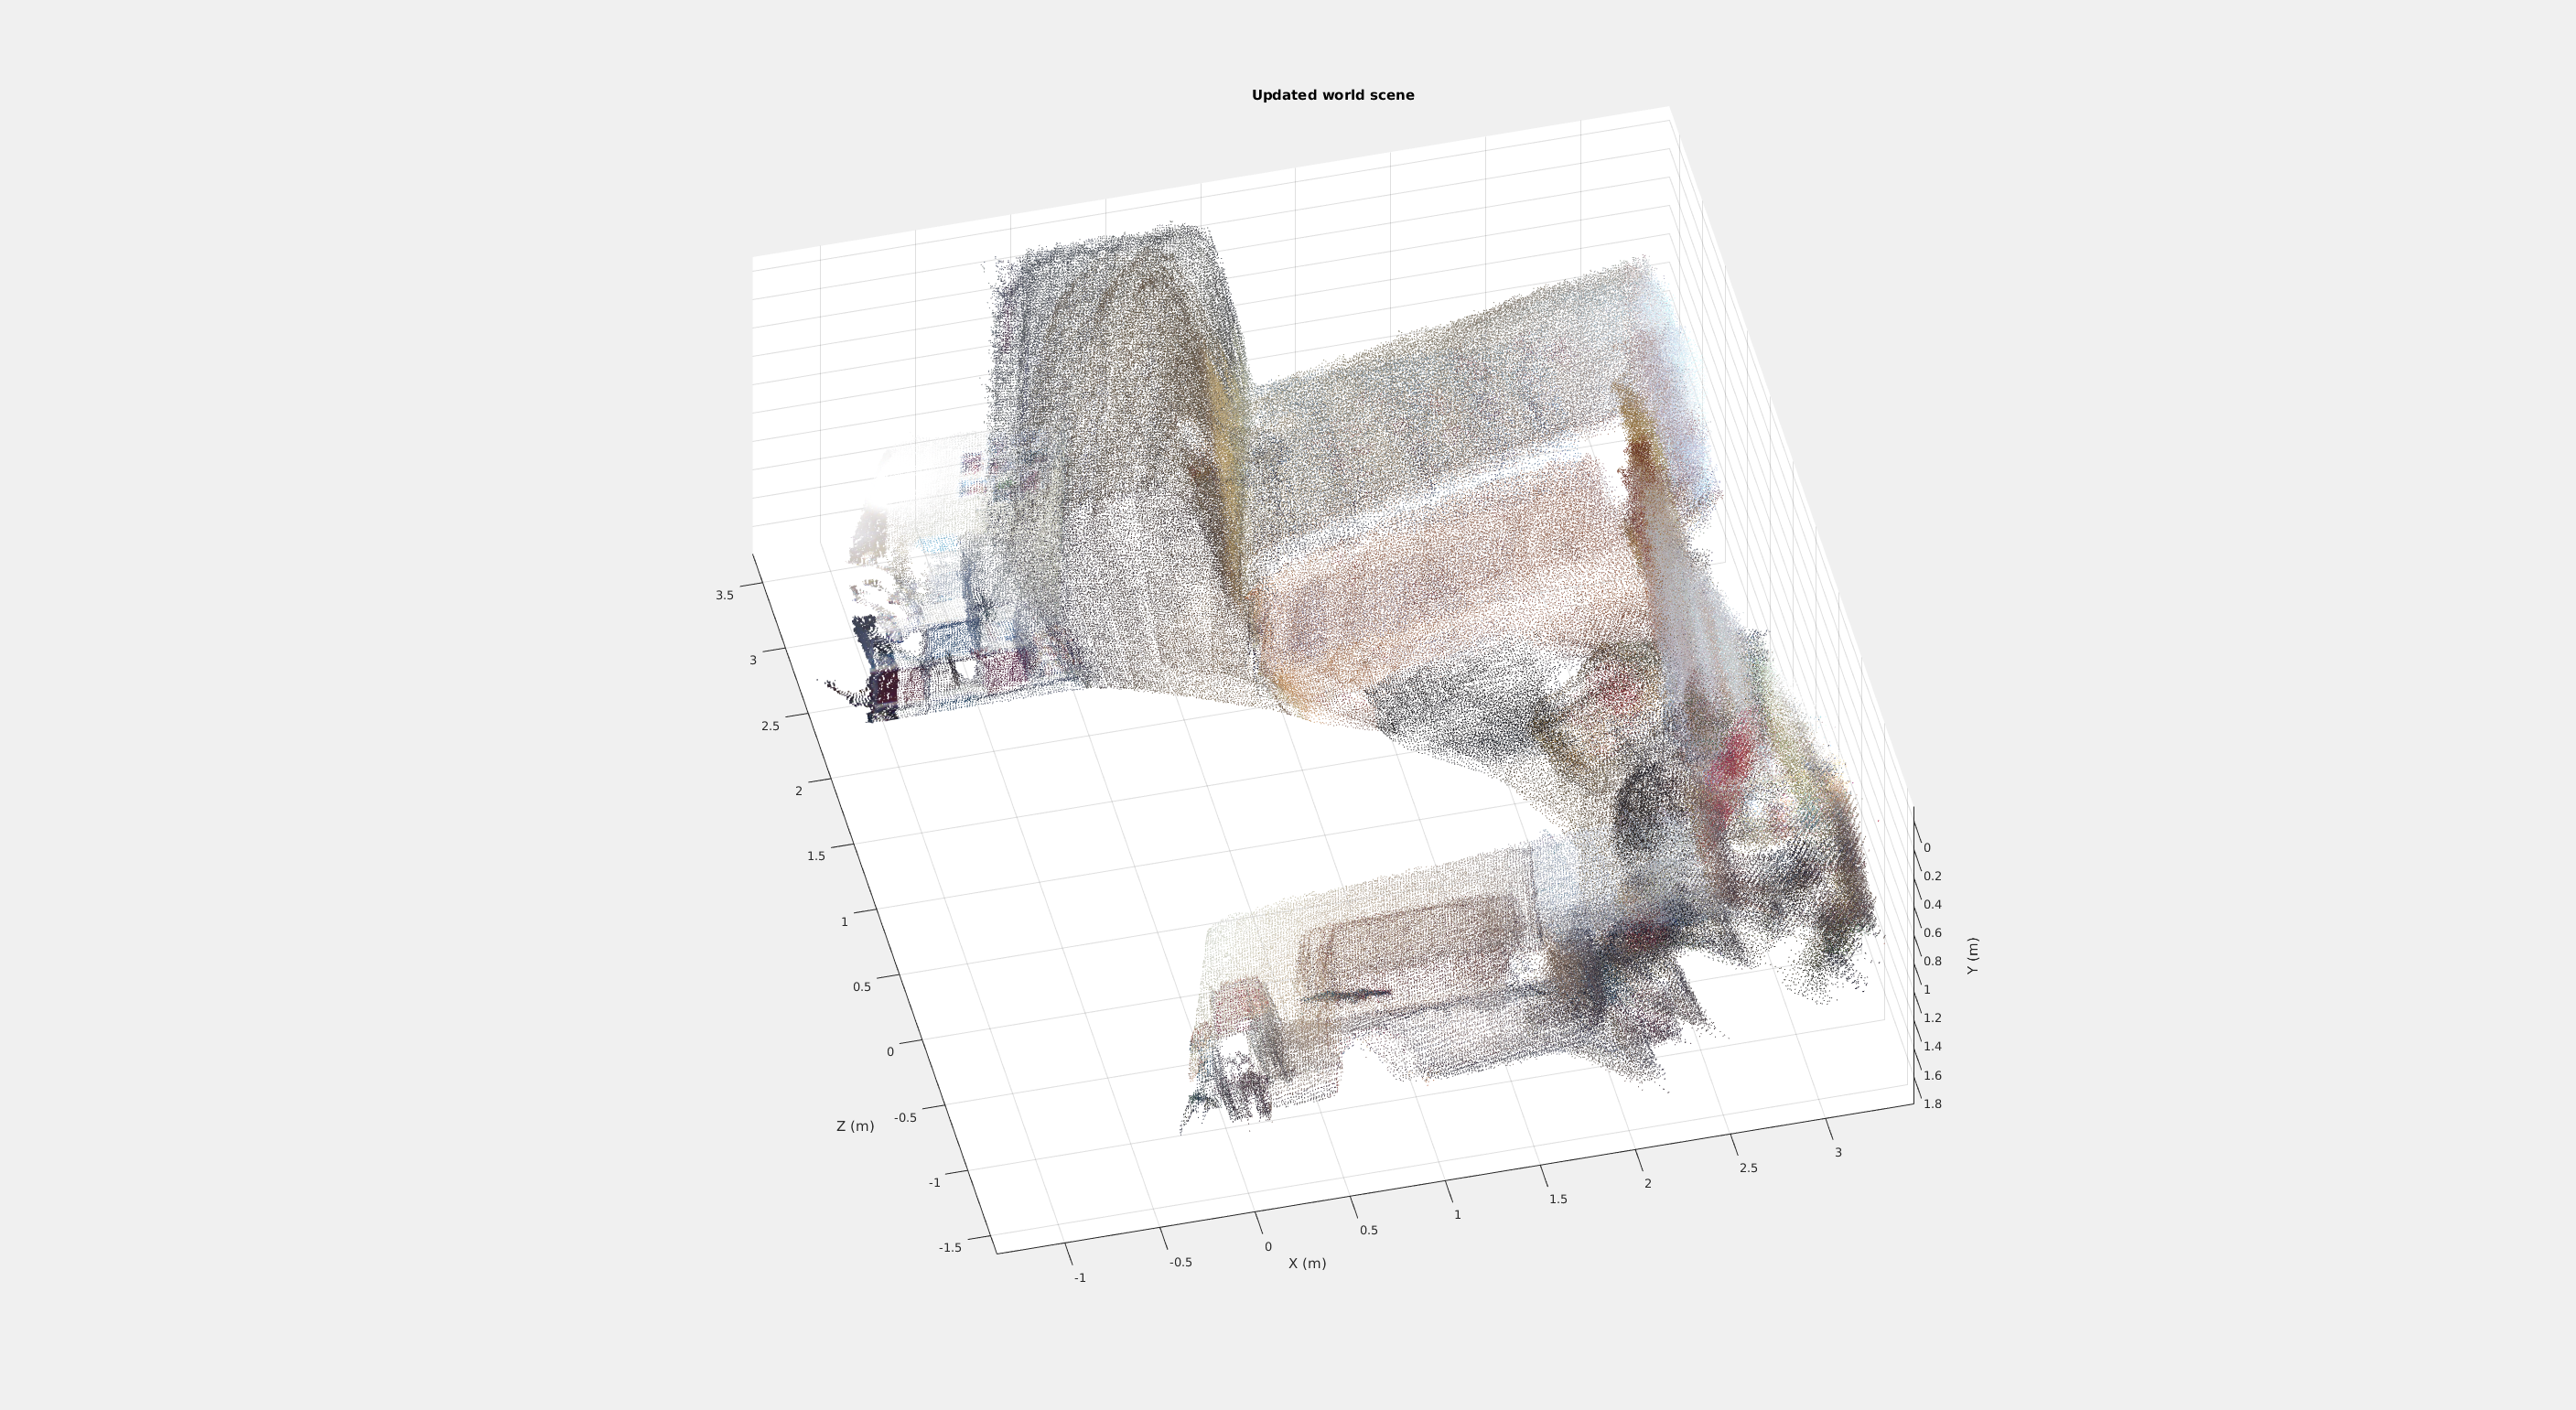

% During the recording, the Kinect was pointing downward. To visualize the
% result more easily, let's transform the data so that the ground plane is
% parallel to the X-Z plane.
angle = -pi/10;
A = [1,0,0,0;...
     0, cos(angle), sin(angle), 0; ...
     0, -sin(angle), cos(angle), 0; ...
     0 0 0 1];
ptCloudScene = pctransform(ptCloudScene, affine3d(A));
pcshow(ptCloudScene, 'VerticalAxis','Y', 'VerticalAxisDir', 'Down', ...
        'Parent', hAxes)
title('Updated world scene')
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')